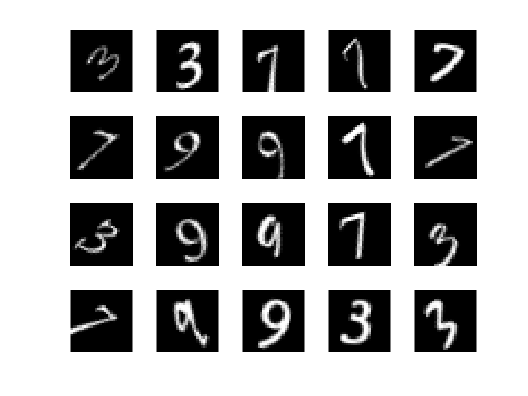

% Dataset
[xTrainImages, tTrain] = digitTrainCellArrayData; % In unserem Fall: Geladene Trainingsdaten
for i=1:20
    subplot(4,5,i);
    imshow(xTrainImages{i});
end

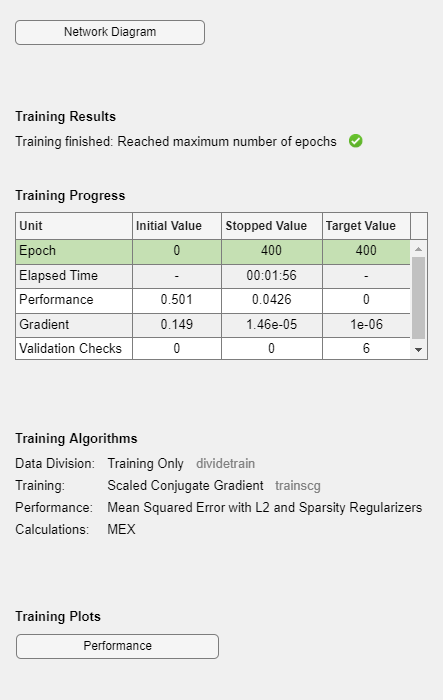

% Train first Autoencoder
rng('default');
hiddenSize1 = 100;

autoenc1 = trainAutoencoder(xTrainImages, hiddenSize1, ...
    'MaxEpochs', 400, ...
    'L2WeightRegularization', 0.04, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.15, ...
    'ScaleData', false);

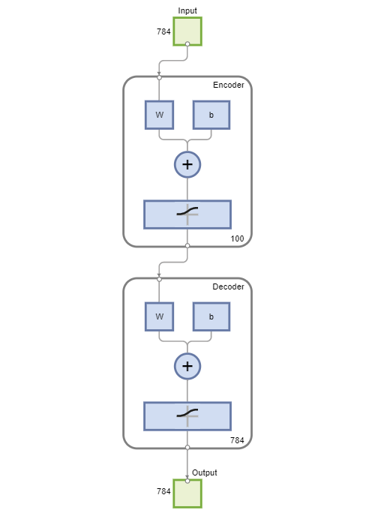


view(autoenc1)

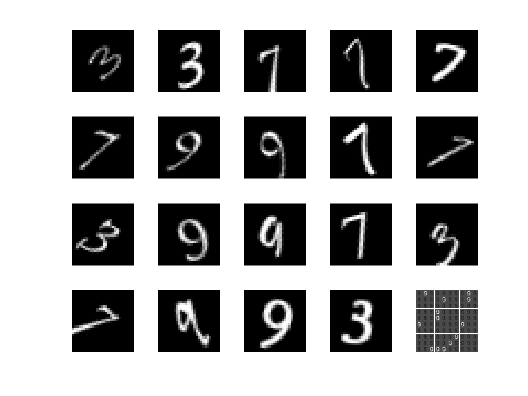

% Plot
plotWeights(autoenc1);


feat1 = encode(autoenc1, xTrainImages);

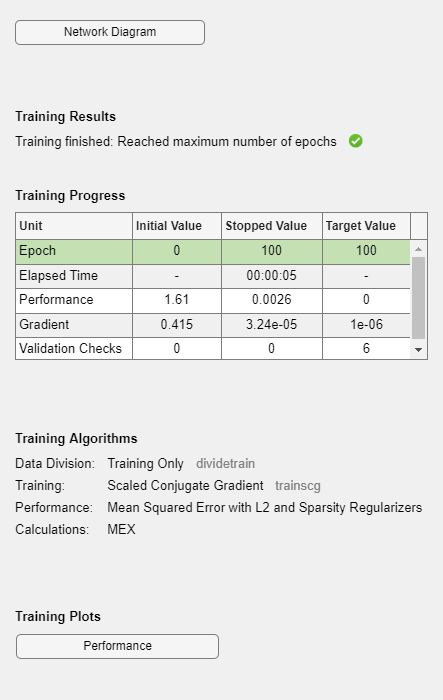

% Trainieren vom 2. Autoencoder
hiddenSize2 = 50;
autoenc2 = trainAutoencoder(feat1, hiddenSize2, ...
    'MaxEpochs', 100, ...
    'L2WeightRegularization', 0.002, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.1, ...
    'ScaleData', false);

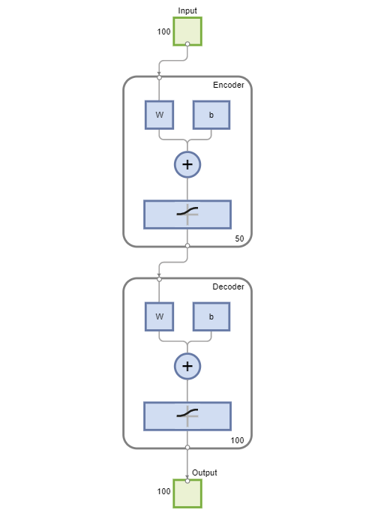


view(autoenc2)


feat2 = encode(autoenc2,feat1);

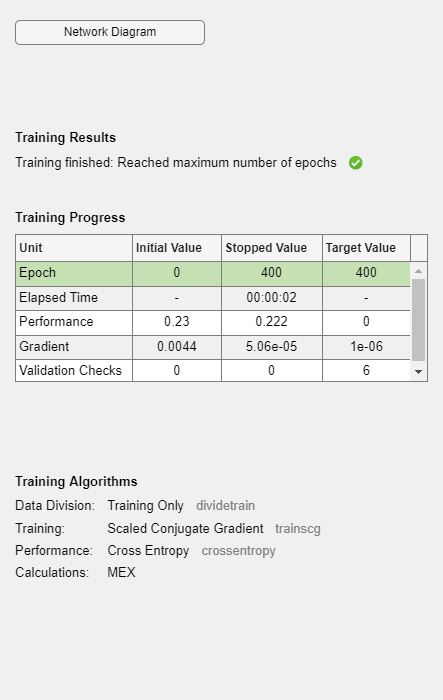

% Softmax-Layer trainieren
softnet = trainSoftmaxLayer(feat2, tTrain, 'MaxEpochs', 400);

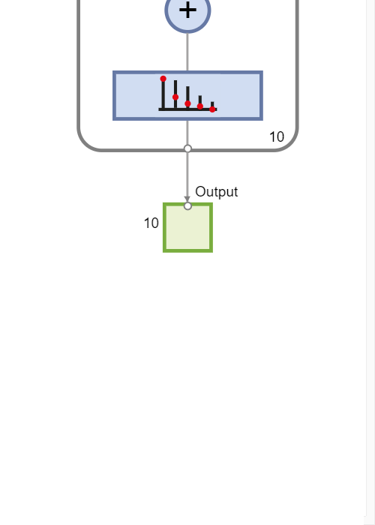

view(softnet)

% StackedNet
stackednet = stack(autoenc1, autoenc2, softnet);

% Bildgröße
imWidth = 28;
imHeight = 28;
inputSize = imWidth * imHeight;

% Laden der Testbilder
[xTestImages,tTest] = digitTestCellArrayData;

% Testbilder in Vektoren und die Rüstung
xTest = zeros(inputSize, numel(xTestImages));
for i = 1:numel(xTestImages)
    xTest(:,i) = xTestImages{i}(:);
end

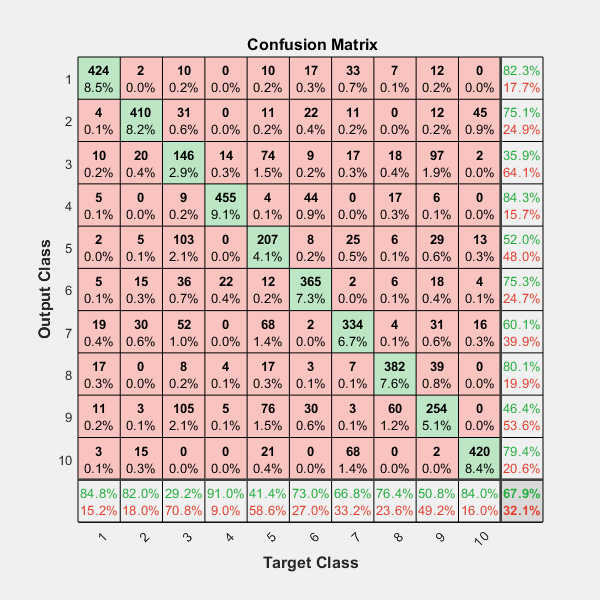

% Visualisieren
y = stackednet(xTest);
plotconfusion(tTest,y);

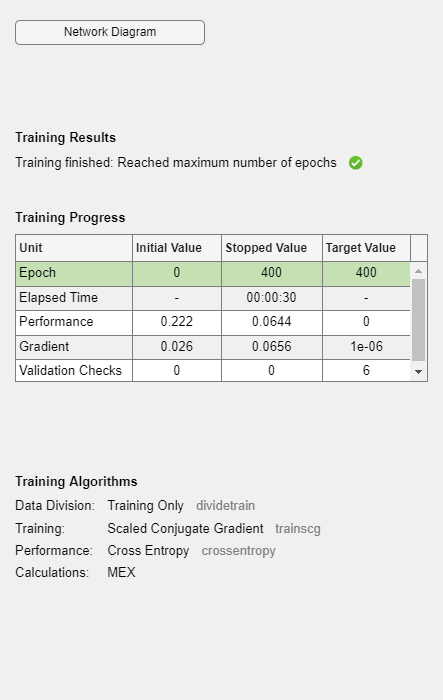

% In Vektor umwandeln
xTrain = zeros(inputSize, numel(xTrainImages));
for i=1:numel(xTrainImages)
    xTrain(:, i) = xTrainImages{i}(:);
end

stackednet = train(stackednet, xTrain, tTrain);

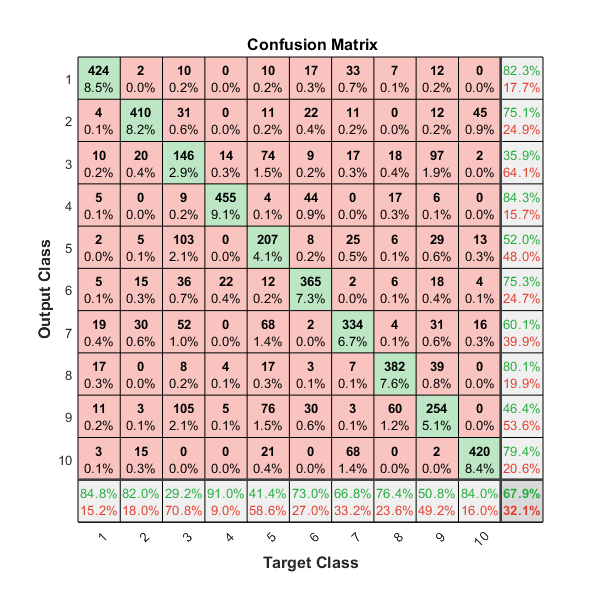

y = stackednet(xTest);
plotconfusion(tTest,y);